# `Dinámica de una partícula en un potencial de doble pozo`

`Modelado de Sistemas Dinámicos`

`Nombre: Sergio`

`Fecha: 24/04/2026`

## `Resumen`

`En este trabajo se analiza la dinámica de una partícula en un potencial de doble pozo. Se estudian los puntos de equilibrio y su estabilidad, se implementa el modelo en MATLAB y Simulink. Se realizan simulaciones numéricas mediante el método de Runge-Kutta de orden 4.`

## `Introducción`

`El estudio de sistemas dinámicos en potenciales no lineales permite comprender fenómenos físicos complejos. El potencial de doble pozo es un modelo clásico que presenta múltiples puntos de equilibrio y comportamientos oscilatorios.`

`El objetivo de este trabajo es analizar la dinámica del sistema y estudiar su comportamiento bajo distintas condiciones iniciales y parámetros.`

## `Modelo matemático`

#### Potencial


$$V\left(x\right)=a*x^4 -b*x^2$$



$$\frac{\mathrm{dV}}{\mathrm{dx}}=4^* a*x^3 -2*b*x$$


####  Ecuación del movimiento


$$m*x\prime \prime =\frac{\mathrm{dV}}{\mathrm{dx}}$$


####  Sistema de primer orden


$$\begin{array}{l}
x_1 =x\\
x_2 =\frac{\mathrm{dx}}{\mathrm{dt}}\\
x_1 \prime =x_2 \\
x_2 \prime =-\left(\frac{4*a}{m}\right)*x^3 +\left(\frac{2*b}{m}\right)*x
\end{array}$$


#### Puntos de equilibrio y estabilidad


$$x*\left(4*a*x^2 -2*b\right)=0$$


Las soluciones de la ecuacion de grado 3 anterior son:


$$\begin{array}{l}
x=0\\
x=\pm \sqrt{\frac{b}{2*a}}
\end{array}$$


Ahora es necesario evaluar estos puntos en la segunda derivada de la función V(x) para conocer si el punto es un maximo, minimo o punto de silla. En el caso de ser maximo, el punto es inestable, si es un minimo, el punto es estable y en el caso de ser un punto de silla, la estabilidad no es concluyente con solo esta información.


$$\mathrm{V"}\left(x\right)=12*a*x^2 -2*b$$


Por tanto, teniendo en cuenta que los parametros a y b son constantes positivas, se obtiene que:


$$\begin{array}{l}
\mathrm{V"}\left(0\right)=-2b<0\\
V\left(\pm \sqrt{\frac{b}{2*a}}\right)=4b>0
\end{array}$$


Por tanto, se deduce:


$$\begin{array}{l}
x=0\to \mathrm{inestable}\\
x=\pm \sqrt{\frac{b}{2*a}}\to \mathrm{estables}
\end{array}$$


#### Uso de Simulink y ejecución de la simulación

Para poder realizar las simulaciones en Simulink es necesario construir el modelo, es decir, el sistema de ecuaciones de primer orden:


$$\begin{array}{l}
x_1 =x\\
x_2 =x^{\prime } \\
x_1^{\prime } =x_2 \\
x_2^{\prime } =\frac{-4*a}{m}*x_1^3 +\frac{2*b}{m}*x_1 
\end{array}$$


En la herramienta de SimuLink se ha realizado el diagrama de control para la automatización del proceso y obtención de los datos para el modelo. A continuación se muestra una imagen del diagrama.

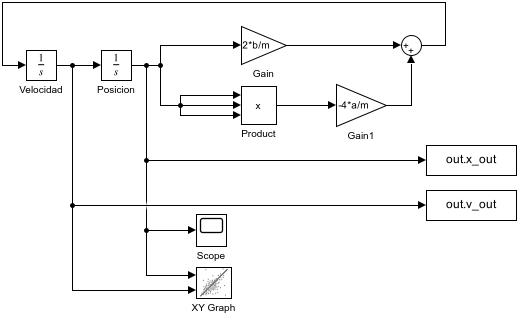

Para la construcción del modelo en Simulink ha sido necesario adaptar la ecuación diferencial de segundo orden a una representación en variables de estado, lo que ha implicado el uso de dos bloques integradores en cascada para obtener la velocidad y la posición a partir de la aceleración. Las condiciones iniciales se han fijado directamente en estos integradores, estableciendo la posición inicial en x(0) = -1.5 y la velocidad inicial en cero.

La expresión de la aceleración se ha implementado mediante bloques matemáticos, utilizando un bloque Product para generar el término cúbico de la posición y bloques Gain para introducir los coeficientes del sistema, ajustados según los valores de los parámetros (a = 1/4 y b = 1/2), lo que resulta en ganancias de -1 y 1 respectivamente. Ambos términos se han combinado mediante un bloque Sum.

Además, se ha cerrado el lazo de realimentación conectando la salida de posición con los bloques que calculan la aceleración, dado que se trata de un sistema autónomo sin entradas externas. Finalmente, se ha configurado el solver de Simulink con un método de Runge-Kutta de orden 4 (ode4), un paso de integración de 0.01 y un intervalo de simulación de 0 a 100 segundos, asegurando así la correcta resolución numérica del sistema.

Con el diagrama ya realizado, es necesario incluir en el espacio de trabajo los valores indicados para las variables para a y b. Esto permite que la ejecucion de este sistema pueda varias segun las variables a y b. Despues se debe ejecutar la simulacion que nos permite obtener los valores de salida necesarios para realizar las graficas y sacar conclusiones.

% Valores de las variables a y b
a=1/4

a = 0.2500

b=1/2

b = 0.5000

% Se toma m=1 como valor base en el caso de no indicarse
m=1
% Carga del modelo y simulacion para obtener los valores de salida
modelo = 'Actividad1';
load_system(modelo)
simOut = sim(modelo);

Error due to multiple causes.

Caused by:
    Error using Actividad1 (line 8)
    Invalid setting in 'Actividad1/Gain' for parameter 'Gain'.
        Error using Actividad1 (line 8)
        Error evaluating parameter 'Gain' in '

Habiendo ya ejecutado el modelo, es posible hacer uso en el espacio de trabajo de las variables de salida obtenidas y así poder crear los graficos deseados.

t = x_out.time;
x = x_out.signals.values;
v = v_out.signals.values;

figure
subplot(2,1,1)
plot(t,x,'LineWidth',1.5)
title('Posición vs tiempo')
xlabel('t'); ylabel('x')

subplot(2,1,2)
plot(t,v,'LineWidth',1.5)
title('Velocidad vs tiempo')
xlabel('t'); ylabel('v')